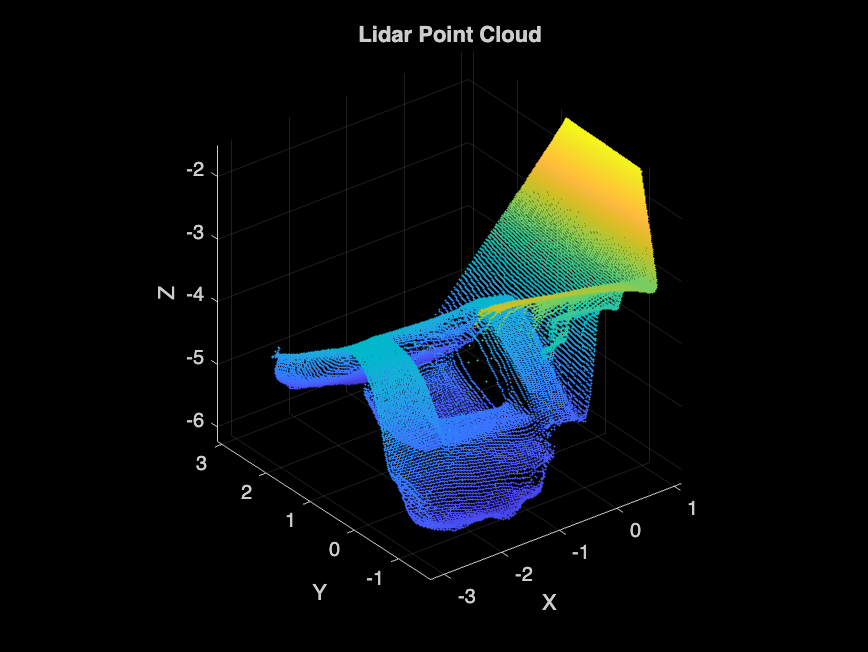

% Needs to be in the same folder as the fiels
lidardepth = readtable("lidar_depth.csv");
midaspointcloud = readtable('midas_point_cloud.csv');
lidar_depth = lidardepth{:,:};
midas_depth = midaspointcloud{:,:};
lidar_point_cloud = pointCloud(lidar_depth);
midas_point_cloud = pointCloud(midas_depth);

% Plot lidar point cloud
pcshow(lidar_point_cloud)
title("Lidar Point Cloud")
xlabel('X');
ylabel('Y');
zlabel('Z');

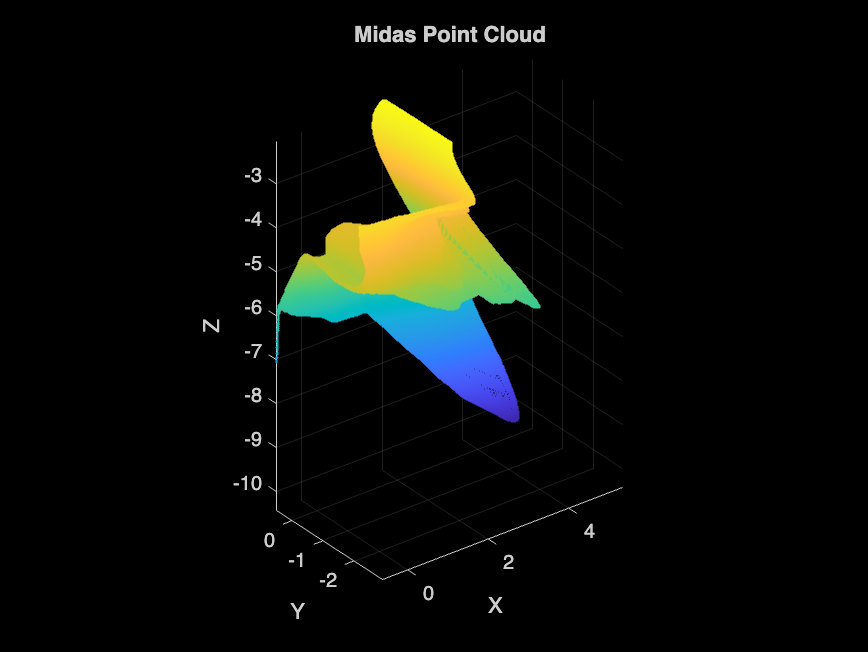

% Plot Midas point cloud
pcshow(midas_point_cloud)
title("Midas Point Cloud")
xlabel('X');
ylabel('Y');
zlabel('Z');

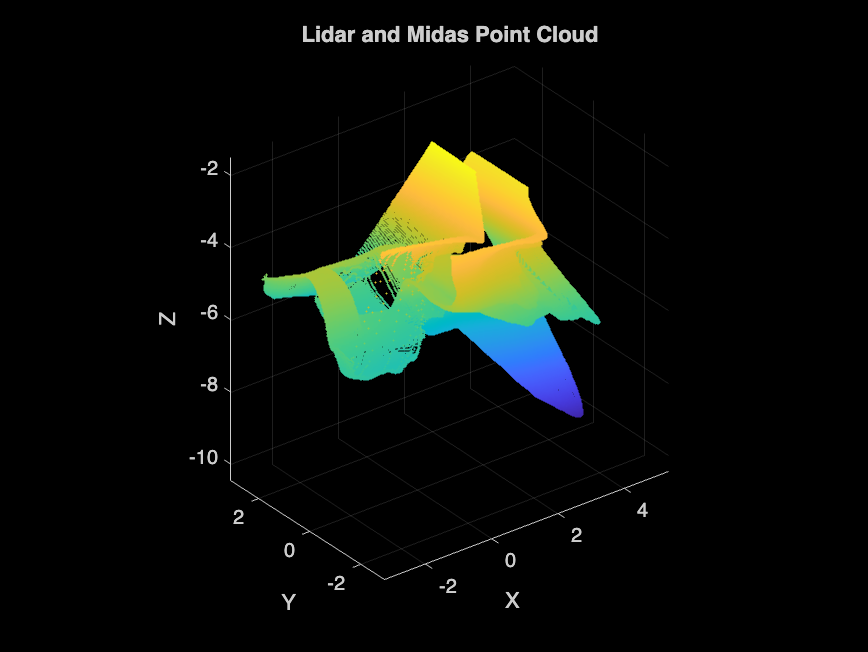

% Plot both point clouds
pcshow(lidar_point_cloud)
hold on
pcshow(midas_point_cloud)
title("Lidar and Midas Point Cloud")
xlabel('X');
ylabel('Y');
zlabel('Z');

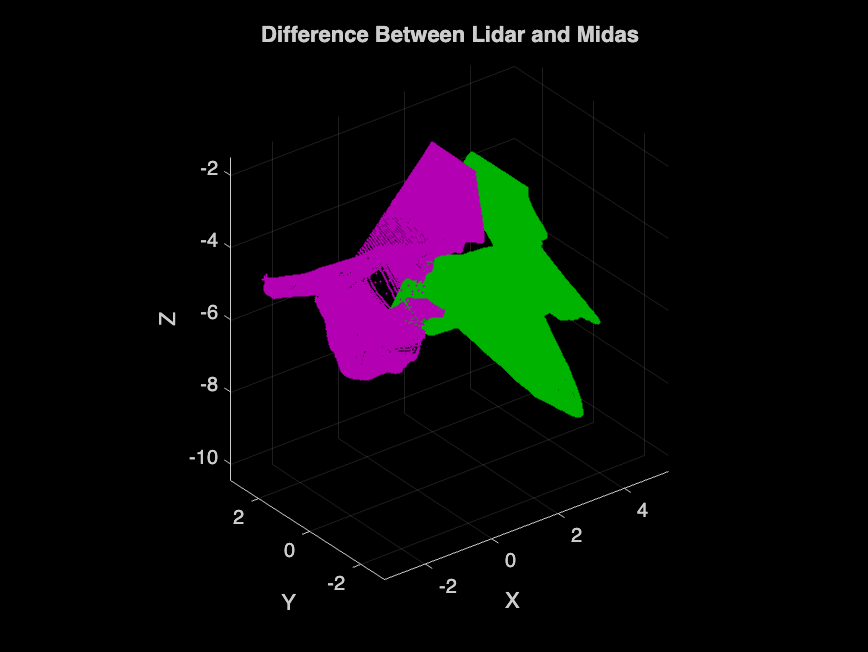

% Plot difference 
figure
pcshowpair(lidar_point_cloud, midas_point_cloud)
title("Difference Between Lidar and Midas")
xlabel('X');
ylabel('Y');
zlabel('Z');